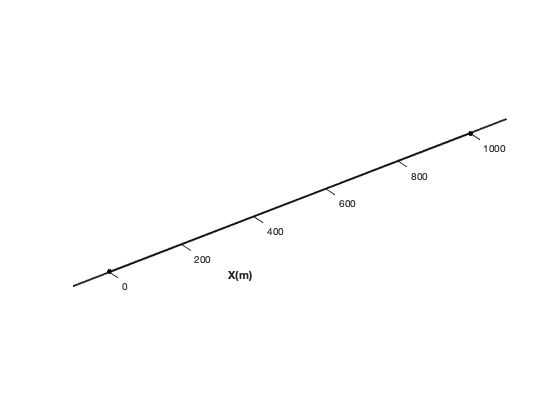

% Create a simulator object
sim = Sim();

% Disable Radar initialization, since this example uses
% a single lane on the ground
sim.en_init_radar = false;

% Define a single-lane LBSD object
lane_length_m = 1000;
num_lanes = 1;
lbsd = LBSD.genSimpleLanes(lane_length_m*ones(1,num_lanes));
sim.lbsd = lbsd;

% Initialize the uas configuration
uas_config = UASConfig();
uas_config.num_uas = 100;

sim.uas_config = uas_config;



figure;
h_lbsd = lbsd.plot();

disp(lbsd.lane_graph.Nodes)

         XData    YData    ZData    Launch    Land    Name 
         _____    _____    _____    ______    ____    _____

    1       0       0        0        1        0      {'1'}
    2    1000       0        0        0        1      {'2'}



disp(lbsd.lane_graph.Edges)

            EndNodes       Weight
         ______________    ______

    1    {'1'}    {'2'}     1000 



sim.initialize(true);

Checking if LBSD is Instantiated
Initializing ATOC
Initializing UAS Dataset
Initializing UAS Trajectories


sim.run_sim()

figure;
num_uas = length(sim.uas_list);
cdata = jet(num_uas);
hold on;
ts = zeros(1,num_uas);
ps{num_uas} = [];
for i = 1:num_uas
    uas = sim.uas_list(i); 
    if ~uas.failed_to_schedule
        t0 = uas.toa_s(1);
        tf = uas.toa_s(2);
        p = uas.exec_traj(:,1);
        ps{i} = p;
        t = linspace(t0,tf,length(p));
        ts(i) = t(1);
        plot(t,p,"Color",cdata(i,:));
    end
end
hold off;

% mins(num_uas - 1)=0;
% for i = 2:num_uas
%     p1 = ps{i-1};
%     p2 = ps{i};
%     l1 = length(p1);
%     l2 = length(p2);
%     l = min(l1,l2);
%     d = abs(p1(1:l)-p2(1:l));
%     mins(i-1)=min(d);
% end
% mind = min(mins);
% disp(["Closest approach: " num2str(mind)])